# Differential Equations: numerical solver

#### by Rodolfo Muñoz

For this instance well go with the simulation of the water level in a Vented Water Tank like the one in the attached figure. 

clc; clear all; close all;

Define global parameters for the problem:

g = 9.8; 
A = pi*2^2;
Av = pi*0.1^2;

Then the interval for the solution $t=\left\lbrack 0,1000\right\rbrack$ and the initial condition $h_0 =10$

tspan = [0 1e3];
h0 = 10;

With that, we define the ordinary differential equation as $\frac{d\;h}{\textrm{dt}}=\textrm{ode}\left(t,h\right)$ 

odefun = @(t,h) -sqrt(2*g*(Av^2/(A^2-Av^2))*h);
[t,h] = ode45(odefun, tspan, h0);
[h_min,idx] = min(abs(h));

And see the results in a graph

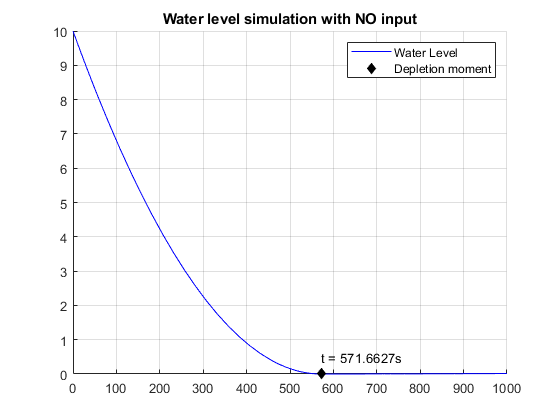

figure; hold on;
plot(t,abs(h),'b');
plot(t(idx),h_min,'kd','MarkerFaceColor',[0 0 0])
legend({'Water Level','Depletion moment'})
text(t(idx),h_min+max(abs(h))/20,['t = ' num2str(t(idx)) 's'])
title('Water level simulation with NO input')
grid on

## Implicit differential equation

The whole problem, when there is an input water source $Q\left(t\right)=\left\lbrace \begin{array}{ll}
\mathrm{Amp} & ,\;\mathrm{for}\;t\ge \mathrm{start}\\
0 & ,\;\mathrm{otherwise}
\end{array}\right.$, corresponds to a second order differential equation so it must be solved implicitly. For that, we define a function $\mathrm{ode}\left(t,h,h_p \right)$ where $h_p =\frac{d\;h}{\mathrm{dt}}$ to model the whole situation:

clc; clear all; close all;
g = 9.8; 
A = pi*2^2;
Av = pi*0.1^2;
% Q = 0.44; % Equlibrium with Q = A*sqrt(2*g*(Av^2/(A^2-Av^2))*10)
Amp =  0.3;
start = 220;
Q = @(t) Amp*(t>=start);
odefun = @(t,h,hp) hp^2 + 2*g*h - (A/Av*hp - Q(t)/Av)^2;

Then we calculate consistent initial conditions where $\mathrm{ode}\left(t_0 ,h_0 ,h_{\mathrm{p0}} \right)=0$

We'll use the initial case, when there was no input Q, as our first guess for the initial values would be that the tanks starts to fill: 

t0 = 0;
h0 = 10;
hp0 = -1;%sqrt(2*g*h0);
[h0,hp0] = decic(odefun,t0,h0,1,hp0,0)

h0 = 10

hp0 = -0.0350

With that the solve the implicit equation as follows:

tspan = [0 5e3];
[t,h] = ode15i(odefun,tspan,h0,hp0);
[~,idx] = min(abs(t-start));

And check the results in a graph:

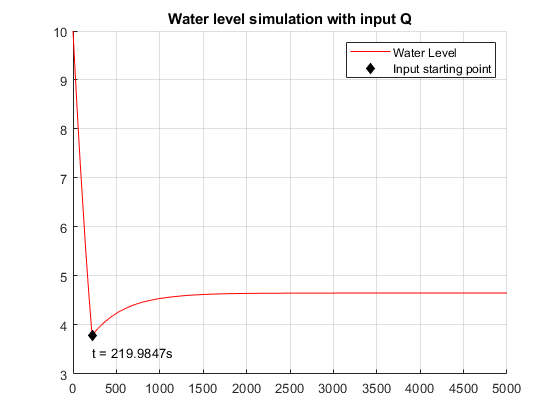

figure; hold on;
plot(t,abs(h),'r');
plot(t(idx),h(idx),'kd','MarkerFaceColor',[0 0 0])
legend({'Water Level','Input starting point'})
text(t(idx),h(idx)-max(abs(h))/30,['t = ' num2str(t(idx)) 's'])
title('Water level simulation with input Q')
grid on